## List files

Find all data files in the '\EnvNoiseDetector\data\DataExamples' directory. 

% Find base directory
basedir = fileparts(pwd);

% Feature storage directory and file name
featuredir = fullfile(basedir,"data","Features");
featurefilename = "FeaturesSNR10Octaves";

% Find data examples directory
datadir = fullfile(basedir,"data","DataExamplesv2");

% File descriptions
fileDescripts = readtable(fullfile(datadir,"FileDescriptions.xlsx"),'TextType','string');
fileDescripts.AircraftPresent = fileDescripts.AircraftPresent == "Y";
fileDescripts.Contaminated = fileDescripts.Contaminated == "Y";

contaminationFiles = fileDescripts.FileName(fileDescripts.Contaminated);
signalFiles = fileDescripts.FileName(~fileDescripts.Contaminated);

% Create pool of MATLAB workers
% tic; parpool('local',4); toc


## Processing parameters

List and define processing parameters.

% record or block duration (s)
tblock = 1;

% fractional overlap between blocks, 0 <= foverlap <= 1
foverlap = 0.25;

% frequency limits for octave
freqlim = [30 20000];

% Bands per octave
nbpo = 1;

% Signal to noise ratio
snrdB = 10;
snratio = 10^(snrdB/10);

## Signal files

Read in clean signal files. Store them in two cell arrays: 

- Store the full 1-D signal in x_1Dsignals

- Store the spectral reshaped signal in xBlockSignals

The different forms of a given signal need to be used together in wavelet signal processing 

% Loop over all signal files
xBlockSignals = cell(length(signalFiles),1);
x_1Dsignals = cell(length(signalFiles),1);
fc = cell(length(signalFiles),1);
for ifile = 1:length(signalFiles)
    % Load file
    [x,fs] = audioread(fullfile(datadir,signalFiles(ifile)));
    % Convert processing parameters to samples
    nblock = tblock*fs;
    noverlap = round(foverlap*nblock);
    
    xblock = spectralReshape(x,noverlap,nblock);
    x_1Dsignals{ifile} = x; 
    xBlockSignals{ifile} = xblock;
end

Now repeat the same process for contaminated signal files

% Make contamination signal assignments
% one contamination file index for each of the signal files
rng(42);
contaminationAssign = randi(length(contaminationFiles),1,length(signalFiles));

% Process signal files one at a time and add contamination signals
xcntm_blockSignals = cell(length(signalFiles),1);
xcntm_1Dsignals = cell(length(signalFiles),1);
for ifile = 1:length(signalFiles)
    contaminationFilesLocal = contaminationFiles;
    % Load files
    [x,fs] = audioread(fullfile(datadir,signalFiles(ifile)));
    [n,fn] = audioread(fullfile(datadir,contaminationFilesLocal(contaminationAssign(ifile))));
    assert(fs == fn,'featureGenerator:UnequalSampleRates',...
        'Sample rates for the signal data and the contamination data are not equal.')
    
    % Adjust contamination signal length
    n = repmat(n,ceil(length(x)/length(n)),1);
    n = n(1:length(x));
    
    % Adjust signal-to-noise ratio
    signalPow = rssq(x(:)).^2;
    noisePow  = rssq(n(:)).^2;
    n = sqrt(signalPow/noisePow/snratio)*n;
    assert(abs(snr(x,n)-snrdB) <= 0.1,'featureGenerator:SignaltoNoiseRatioError',...
        'Error scaling noise signal power for request signal-to-noise ratio.')
    
    % Convert processing parameters to samples
    nblock = tblock*fs;
    noverlap = round(foverlap*nblock);
    
    
    % Super impose signal and noise together
    x = x + n;
    
    %Store them 
    xcntm_1Dsignals{ifile} = x; 
    
    xblock = spectralReshape(x,noverlap,nblock);
    xcntm_blockSignals{ifile} = xblock;
end

## **Looking at Power Spectral Densities **

Let's get a sense of the signals with which we are working. Recall that the Discrete Wavelet Transform divides an *N-*length signal into at most ~$[\frac{log_2(N) }{waveletN}]$ levels (subands) where waveletN is the length of the wavelet. This can be computed in matlab using the `L = wmaxlev(S,wname) `function. If we wish to examine the signal in greater detail in time-frequency joint space at higher and higher frequency levels, then more levels need to be therefore used. The purpose of this analysis is to determine if there is significant frequency content in the upper regimes, as means of determining if a large number of DWT levels (and thereby computational complexity) need be required. 

Let's first examine one of the clean aircraft signals. This frequency representation is generally emblematic of this group of signals. We choose the 5th signal arbitrarily. 

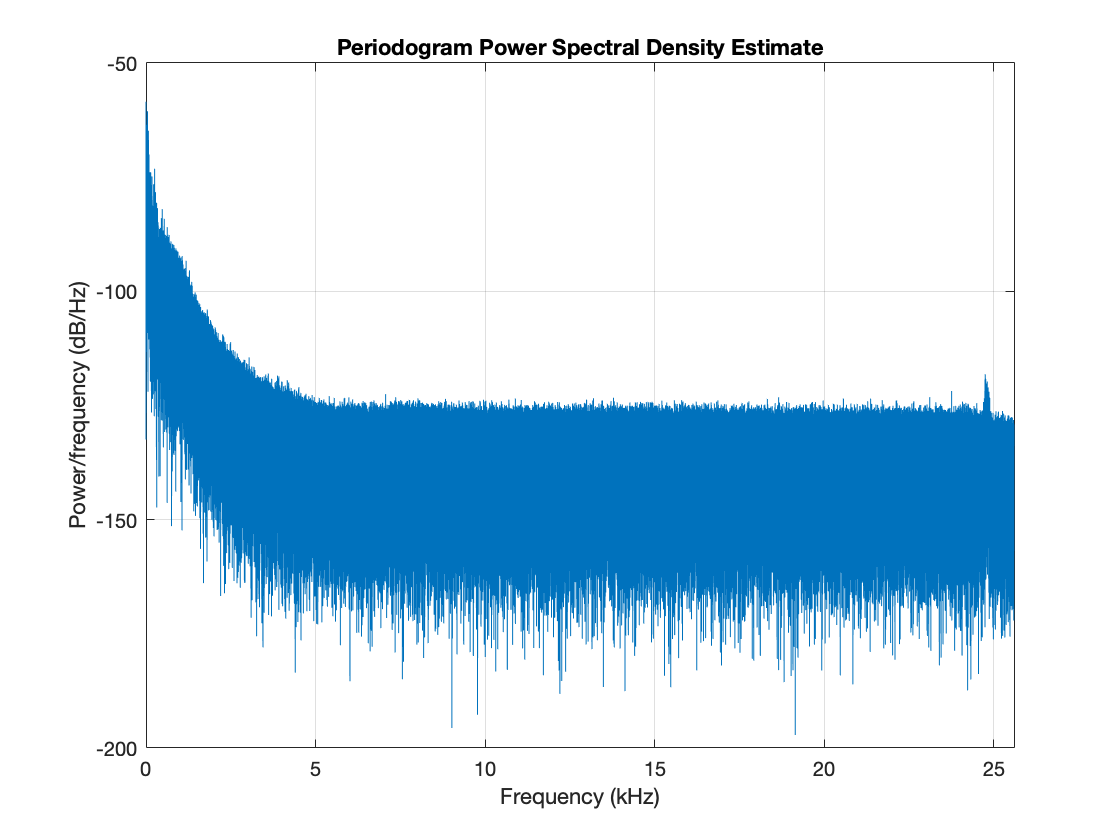

psd(spectrum.periodogram, x_1Dsignals{5},'Fs',fs);

And now view the spectral density of one of the contaminated signals. Although these signals vary more, they all possess the characteristic of having more excitations in the higher frequency regimes. 

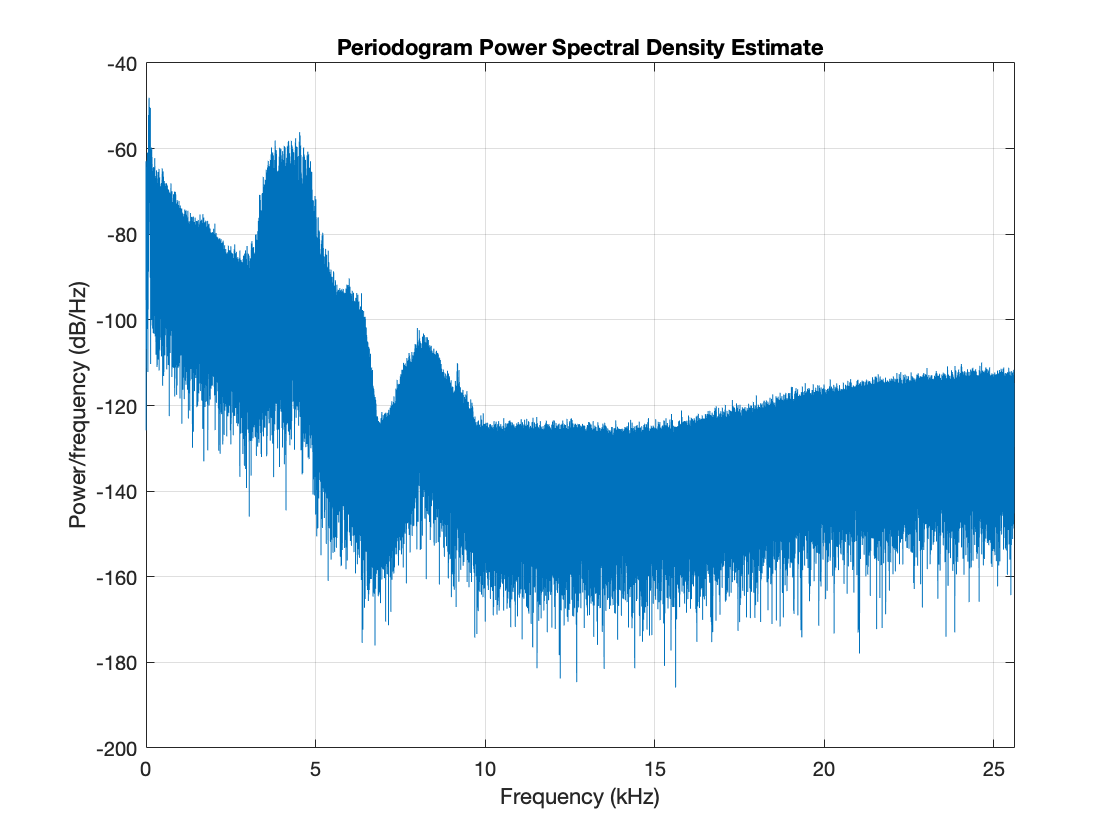

psd(spectrum.periodogram, xcntm_1Dsignals{12},'Fs',fs);

#### Discussion 

If we utilize the DWT, then the subands produced would lie on the aforementioned dyadic/logarthmic scale i.e. a  2-level DWT would result in appx  ranges [0,12 kHZ] and [12, 25 kHZ] while a 4-level DWT would result in frequency bands of [0-12], [12-20], [20-22.5] and [22.5-25] kHZ approximately. If most of the frequency content pertinent to this project lies in the former bands, then it is not necessary to use high-level DWTs. The signal lengths of the .wav files are quite long and it would be possible to use double digit-sized levels, and some of the research literature discussed in the literature review on wavelets discuss the efficacy of these higher-order level decimations. However as we see here, that is not necessary and the standard 3-4 level DWTs will suffice and be used henceforth. 

We can also view the joint time-frequency spectrogram of the DWT, sample code below. Arbitrarily using the 30th clean signal . We also view the energies by subband/node, demonstrating that indeed most of the signal energy is in the first node (lower frequencies). 

testX = x_1Dsignals{30}; 
t = 1:length(testX); 
dt = 1; 
figure
[wpt,packetLevels,F, energy] = modwpt(testX,'TimeAlign',true);
contour(t,F.*(1/dt),abs(wpt).^2)
grid on
xlabel('Time (secs)')
ylabel('Hz')
title('Time-Frequency Analysis -- Undecimated Wavelet Packet Transform')


%View energies by node 
figure
bar(1:16,energy)
xlabel('Node')
ylabel('Energy')
title('Energy by Node')

### Feature Extraction

The literature discussed concerning wavelets outline various methods for extracting key features from the wavelet transforms. **<Add References!>**. 

One set of features use: 

- The mean of the absolute value of the coefficients in each subband.  

- The standard deviation of the coefficients in  each subband. 

- The ratios of the means of the coefficients between adjacent subbands. 

It would be possible to gather these features using Matlab's `[c,l] = wavedec(x,n,wname)`functionality which decomposes the wavelet transform and coeffcients by level of interest. 

Another set of features uses the Shannon Entropy of the undecimated Discrete Wavelet *Packet* Transform (**insert minor discussion on DWPT) **at each level. 

A third set of features is based on wavelet variance. The wavelet variance for the entire signal is obtained using `modwtvar`. Wavelet variance measures variability in a signal by scale, or equivalently variability in a signal over octave-band frequency intervals. (https://www.mathworks.com/examples/wavelet/mw/wavelet-ex52408711-signal-classification-using-wavelet-based-features-and-support-vector-machines). 

Functions for generating the latter two feature sets are below. They are addapted from helperExtractFeatures.m from the url link above. 

Entropy Features 

The code below generates the entropy feature matrix. It takes ~20 min so the matrix has been precomputed and stored in the .mat file. We load it here but the user can uncomment this section to re-produce it. 

% see shannonEntropy.m

%%%%% LOAD .MAT FILES %%%%%%%

load('XEntropyMatrix.mat');
load('XCNTMEntropyMatrix.mat');


%Function that genereates an entropy "feature" matrix for all signals 

%%%%% UNCOMMENT THIS IF WANT TO RECREATE %%%%%%%%
% % On non-contaminated signals: 
% entropies = cell(length(signalFiles),1);
% level = 4;
% for idx =1:size(entropies,1)
%     x = xBlockSignals{idx};    
%     x = detrend(x,0);
%     blocks = size(x,2);
%     se = shannonEntropy(x,level);
%     entropies{idx} = se; %#ok<AGROW>
% end
% %Entropies are of different length, find the minimum length entropy
% %"vector" and truncate rest to fit 
% min_dim = 9999; 
% for i=1:length(entropies)
%     s = size(entropies{i});
%     if (s(2) < min_dim)
%         min_dim = s(2);
%     end
% end
% %Generate entropy matrix 
% entropy_matrix = [];
% for i = 1:length(entropies)
%     e = entropies{i};
%     entropy_matrix = [entropy_matrix; e(1:min_dim)]; 
% end
% 
% % On contaminated signals: 
% cmt_entropies = cell(length(signalFiles),1);
% for idx =1:size(cmt_entropies,1)
%     x = xcntm_blockSignals{idx};
%     x = detrend(x,0);
%   
%     blocks = size(x,2);
%     se = shannonEntropy(x,level);
% 
%     cmt_entropies{idx} = se; %#ok<AGROW>
% end
% %Entropies are of different length, find the minimum length entropy
% %"vector" and truncate rest to fit 
% min_dim = 9999; 
% for i=1:length(cmt_entropies)
%     s = size(cmt_entropies{i});
%     if (s(2) < min_dim)
%         min_dim = s(2);
%     end
% end
% %Generate entropy matrix 
% ctm_entropy_matrix = [];
% for i = 1:length(cmt_entropies)
%     e = cmt_entropies{i};
% 
%     ctm_entropy_matrix = [ctm_entropy_matrix; e(1:min_dim)]; 
% end
% 

%Add labels and concatenate the two vertically 
AA = [entropy_matrix, zeros(1,size(entropy_matrix,1))'];
BB = [ctm_entropy_matrix, ones(1,size(ctm_entropy_matrix,1))'];
entropyFeatureMatrix = [AA;BB];

Wavelet Variance Features 

% Run on clean signals 
WaveletVarianceMatrix = [];
for idx =1:length(x_1Dsignals)
    fprintf("Computing variance coefficents for clean signal number %d", idx);
    x = x_1Dsignals{idx};
    x = detrend(x,0);
    wvar = modwtvar(modwt(x,3));
    WaveletVarianceMatrix = [WaveletVarianceMatrix; wvar']; 

end

%Run on contaminated signals 
CTM_WaveletVarianceMatrix = [];
for idx =1:length(xcntm_1Dsignals)
    fprintf("Computing variance coefficents for contam signal number %d", idx);
    x = xcntm_1Dsignals{idx};
    x = detrend(x,0);
    wvar = modwtvar(modwt(x,3));
    CTM_WaveletVarianceMatrix = [CTM_WaveletVarianceMatrix; wvar']; 
end

WaveletVarianceMatrix = [WaveletVarianceMatrix, zeros(1, 59)'];
CTM_WaveletVarianceMatrix = [CTM_WaveletVarianceMatrix, ones(1, 59)'];
Master_WaveletVarianceMatrix = [WaveletVarianceMatrix; CTM_WaveletVarianceMatrix];